# Pre Lab 1

Bar Yerushalmian

Ben Efrath

## Q1

% a) Double zero matrix
m1 = zeros(5,5,"double")

m1 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



% b) Double matrix with 0.134
m2 = zeros(5,5,"double")+double(0.134)

m2 =     0.1340    0.1340    0.1340    0.1340    0.1340
    0.1340    0.1340    0.1340    0.1340    0.1340
    0.1340    0.1340    0.1340    0.1340    0.1340
    0.1340    0.1340    0.1340    0.1340    0.1340
    0.1340    0.1340    0.1340    0.1340    0.1340



% c) Double matrix with random values [-1.5, 3.4]
% Given range [a,b] the formula: m = a + (b-a).*rand([5,5])
m3 = -1.5 + (3.4 + 1.5).*rand([5,5],"double")

m3 =    -1.4210    2.2261    0.1267   -0.8654    0.6421
    2.8902    2.6912    2.6148    2.8114    0.3612
    1.0253    0.3761    0.3214   -1.2840    3.3003
    1.1682   -1.0852    2.5583    1.8649    0.4551
    1.4716    2.0960   -0.6351    2.0955    0.6569



% d) Make m3 into uint8 with casting.
% All the negative numbers turned to 0. All fractions were rounded to the
% closest integer. Becasue it's unsigned, it did meet our expectations.
m3 = uint8(m3)

m3 = 5×5 uint8 matrix
   0   2   0   0   1
   3   3   3   3   0
   1   0   0   0   3
   1   0   3   2   0
   1   2   0   2   1



% e) Make 5x5 matrix using uint8 in range of [0,250]
A = uint8(250.*rand([5,5]))

A = 5×5 uint8 matrix
    39    78    21    54   225
    82   102   115   170   105
    79   177     8   139    90
   224    36   188   213   122
    62   218   175   140    64



% f) 
% All The values above 127 are now 255.
A = A.*2

A = 5×5 uint8 matrix
    78   156    42   108   255
   164   204   230   255   210
   158   255    16   255   180
   255    72   255   255   244
   124   255   255   255   128



% g)
% Find the maximum value in the matrix using find().
v = max(A(:))           % value

v = uint8
255

[row,column] = find(A == v)

row =      4
     3
     5
     4
     5
     2
     3
     4
     5
     1


column =      1
     2
     2
     3
     3
     4
     4
     4
     4
     5


## Q2

% a)
% Create unit matrix I1.
I1=eye(3,4,"double")

I1 =      1     0     0     0
     0     1     0     0
     0     0     1     0



% b)
% Create row index matrix I2 and column index matrix I3.
x = 1:4;
y = 1:3;
[I3,I2] = meshgrid(x,y)

I3 =      1     2     3     4
     1     2     3     4
     1     2     3     4


I2 =      1     1     1     1
     2     2     2     2
     3     3     3     3



% c)
% Transform I3 matrix into a vector.
% The function sets the columns of the 
% matrix one after eachother to creare a vector.
I3a = reshape(I3,1,[])

I3a =      1     1     1     2     2     2     3     3     3     4     4     4



% d)
% We didnt get the same vector. This Vector is like reshape of I2.
% Because we transposed I3 it became I2
% Now it's like the rows are set one after eachother to create a vector.
I3b = reshape(I3.',1,[])

I3b =      1     2     3     4     1     2     3     4     1     2     3     4



% e)
% the vector I3c is similar to the vector I3a.
% we can say that reshape makes a column vector from the matrix and than
% transpose it.
I3c = I3(:).'

I3c =      1     1     1     2     2     2     3     3     3     4     4     4


## Q3

% repmat Is copying the matrix 3 times in the x axes and 2 times in the y
% axes.
A1 = repmat(A,3,4)

A1 = 15×20 uint8 matrix
    78   156    42   108   255    78   156    42   108   255    78   156    42   108   255    78   156    42   108   255
   164   204   230   255   210   164   204   230   255   210   164   204   230   255   210   164   204   230   255   210
   158   255    16   255   180   158   255    16   255   180   158   255    16   255   180   158   255    16   255   180
   255    72   255   255   244   255    72   255   255   244   255    72   255   255   244   255    72   255   255   244
   124   255   255   255   128   124   255   255   255   128   124   255   255   255   128   124   255   255   255   128
    78   156    42   108   255    78   156    42   108   255    78   156    42   108   255    78   156    42   108   255
   164   204   230   255   210   164   204   230   255   210   164   204   230   255   210   164   204   230   255   210
   158   255    16   255   180   158   255    16   255   180   158   255    16   255   180   158   255    16   255   180
   255  

## Q4

% flipud flips the matrix upside down.
A=flipud(A)

A = 5×5 uint8 matrix
   124   255   255   255   128
   255    72   255   255   244
   158   255    16   255   180
   164   204   230   255   210
    78   156    42   108   255


## Q5

## Q6

% imshow show the matrix as an image where every number in the matrix
% represent a level of gray, the square brackets are the range for the gray level.
% it means that 10 is black and 20 is white.
I = uint8(20.*rand([3,5]))

I = 3×5 uint8 matrix
   19    9    4    7   10
    9   14   17    4    9
    5    8   12    4   15


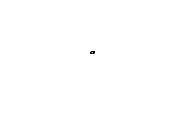

imshow(I ,[10 20])

## Q7